%MAE 180 PROJ S-3 TEAM CODE

clc
clear
format long
global min_distance;% km
global min_distance_time;
global min_distance_r_s1;
global min_distance_r_s2;
min_distance_time = 0;
min_distance = 50;
min_distance_r_s1 = [0;0;0;];
min_distance_r_s2 = [0;0;0;];


%% Common parameters for both runs
lat = 32.8811913;    % Site latitude (phi) in degrees
alt = 111E-3;        % Site altitude in km
JD_prop = 2460542.7792; % Propagation Julian Date (second value given on file)

%% First Run: Group S-3 (ADVENTURE 1)
% Days (JD), right ascension (ra), declination (dec), and local sidereal time (lst)
JD_s1  = [2460262.842373029;
       2460262.842893863;
       2460262.843414696];
   
ra_s1  = [135.514066681081;
       148.057402685433;
       165.762330451468];

dec_s1 = [29.155447177193;
       45.578290874916;
       56.881276513171];

lst_s1 = [59.199692009582;
       59.387705356210;
       59.575718703254];

%% Second Run: Group K-3 (THE MARTIANS)
% Fill in the missing values with the Group K-3 data
JD_s2  = [2460267.322080967;
       2460267.322601800;
       2460267.323122634];
   
ra_s2  = [192.359369943852;
       206.417534213015;
       226.142267971101];

dec_s2 = [-25.796600080803;
       -26.271136667762;
       -25.487019970794];

lst_s2 = [236.309961929603;
       236.497975276648;
       236.685988623275];
%CONSTANTS
mu= 398600.4354; %km^3/s^2
Rearth= 6378.1366; %km
smallomegaearth= 7.2921159E-5; %rad/s
Areatomassratio= 0.0123; %m^2/kg
JDday2secondconversionunit = 86400; 
J2 = 0.0010826267; %unitless
CD = 1.28; % drag coefficient corrected from annocement 
we = 7.2921159E-5;% Earth's inertial rotation rate

% UCSD coords
lot=deg2rad(-117.2336137);

% convert JD to seconds and units to radians
JD_s1 = JD_s1 * JDday2secondconversionunit;
JD_prop = JD_prop * JDday2secondconversionunit;
lat = deg2rad(lat);
lst_s1 = deg2rad(lst_s1);
ra_s1 = deg2rad(ra_s1);
dec_s1 = deg2rad(dec_s1);

JD_s2 = JD_s2 * JDday2secondconversionunit;
lst_s2 = deg2rad(lst_s2);
ra_s2 = deg2rad(ra_s2);
dec_s2 = deg2rad(dec_s2);

[r0_s1,v0_s1] = gauss(lat, lst_s1, alt, ra_s1, dec_s1, JD_s1, JD_prop);
[r0_s2,v0_s2] = gauss(lat, lst_s2, alt, ra_s2, dec_s2, JD_s2, JD_prop);


% 10. Compute initial orbital elements from r0 and v0
oe0_s1 = ComputeOrbitalElements(r0_s1, v0_s1, mu);
oe0_s2 = ComputeOrbitalElements(r0_s2, v0_s2, mu);


% Initial state vector
y0_s1 = [r0_s1';v0_s1';];
y0_s2 = [r0_s2';v0_s2';];

% Satelite 1 starts before satelite 2
% Propegate satelite 1 until the start of satelite 2
% Then propogate them together to find closest distance
A2M_convert = Areatomassratio / 1000000;  % m^2/kg to km^2/kg

JD_init_s1 = JD_s1(2);
JD_init_s2 = JD_s2(2);
t_prop_s1tos2 = JD_init_s2 - JD_init_s1;
tspan_s1tos2 = [0, t_prop_s1tos2];
options = odeset('RelTol',1e-7,'AbsTol',1e-7);
[t_s1tos2, Y_s1tos2] = ode45(@(t, y) one_sat_sim(t, y, mu, J2, Rearth, A2M_convert,CD), tspan_s1tos2, y0_s1, options);

% New positions of our first satelite when the second satelite starts
r0_s1_new = Y_s1tos2(end,1:3);
v0_s1_new = Y_s1tos2(end,4:6);

% Now propogate the satelites at the same time from the same start time
% Compare the distance between each at every step and find the minimum

JD_init = JD_s2(2);
JD_end = JD_prop;
t_prop = JD_end - JD_init;
tspan = [0, t_prop];
options = odeset('RelTol',1e-7,'AbsTol',1e-7);

y0_big = [r0_s1_new'; v0_s1_new'; y0_s2;]

y0_big = 1.0e+03 *

   0.877543702906890
  -0.273578926608038
   6.811948532909926
  -0.001618220848354
  -0.007435697957746
  -0.000082885832559
  -3.769838525508065
  -4.870572806985832
   3.014506061429519
   0.006352967972696



[t, Y] = ode45(@(t, y) two_sat_sim(t, y, mu, J2, Rearth, A2M_convert,CD), tspan, y0_big, options);

r_end_s1 = Y(end,1:3)

r_end_s1 = 1.0e+03 *

   3.644359612931452  -0.815079497521989   5.763494111384169


v_end_s1 = Y(end,4:6)

v_end_s1 =   -6.458737428875308  -0.465985686437128   4.005411953748336


r_end_s2 = Y(end,7:9)

r_end_s2 = 1.0e+03 *

  -6.101338341463245   2.112571515091716   2.230572261306575


v_end_s2 = Y(end,10:12)

v_end_s2 =   -1.346285087429040  -6.946636371076125   2.902058148095369



final_distance = norm(r_end_s1 - r_end_s2)

final_distance =      1.077178285469526e+04



min_distance

min_distance =   24.047097967391448


min_distance_time

min_distance_time =      1.884502188892801e+06


min_distance_r_s1

min_distance_r_s1 = 1.0e+03 *

  -0.626157607194760
   6.032005536626766
   3.242866876800040


min_distance_r_s2

min_distance_r_s2 = 1.0e+03 *

  -0.644529126834891
   6.018086167915373
   3.236011122907007


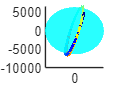




% Downsample the orbit for better performance
step = 500; % Adjust to balance performance & smoothness
Y_downsampled = Y(1:step:end, :);
numPoints = size(Y_downsampled, 1);

% Generate a color gradient
cmap = jet(numPoints);

figure;
hold on;

% Plot Earth
[X, Y2, Z] = sphere(50);
X = X * Rearth;
Y2 = Y2 * Rearth;
Z = Z * Rearth;
surf(X, Y2, Z, 'FaceColor', 'c', 'EdgeColor', 'none'); 
alpha(0.6);


% Plot r0 and r_end with distinct markers (only these go in legend)
scatter3(r0(1), r0(2), r0(3), 150, 'r', 'filled', 'o', 'DisplayName', 'Initial Position');

Unrecognized function or variable 'r0'.

scatter3(r_end(1), r_end(2), r_end(3), 150, 'g', 'filled', 'o', 'DisplayName', 'Final Position');

% Labels and Formatting
xlabel('X (km)');
ylabel('Y (km)');
zlabel('Z (km)');
title('Rainbow Satellite Orbit with J2 Perturbation and Atmospheric Drag');
grid on;
axis equal;
legend('Location', 'best'); % Only shows r0 and r_end
view(3);
hold off;

r = r_end;
v = v_end;